 Схема виртуальной установки

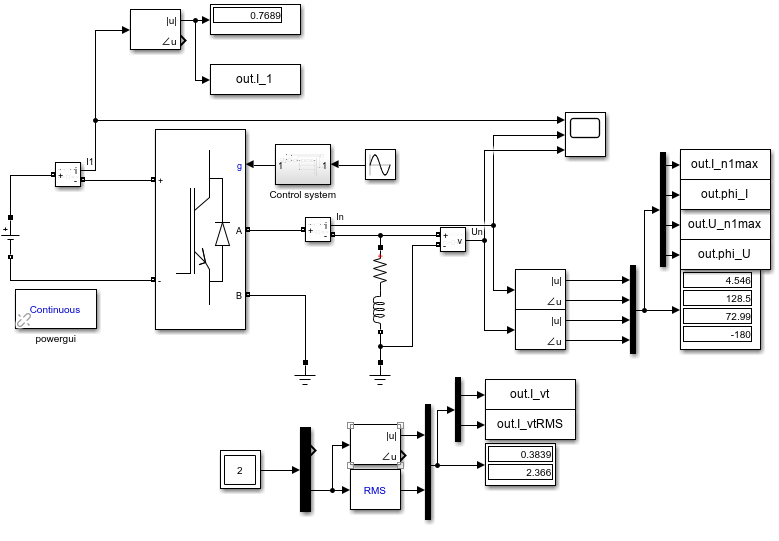

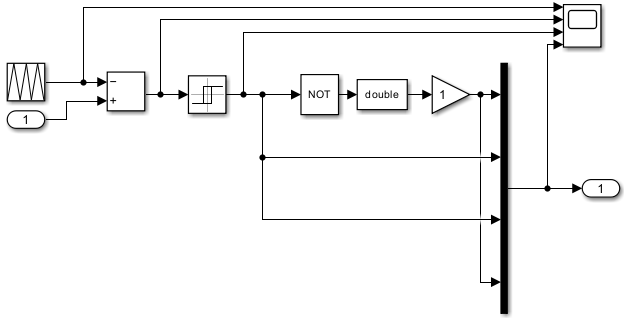

Исходные данные

DC.Voltage = 150;
f_preobr = 350;
f_nes = f_preobr*10;
w_preobr = 2*pi*f_preobr;
Nagr.Res = 1;
U_mod = 1.0;
Nagr.Ind = 2*Nagr.Res / f_nes;

Параметры моста

UB.V_f = 2;
UB.V_fd = 2;
UB.R_on = 0.001;

Подготовка данных моделирования для каждого значения сопротивления нагрузки.

R_n = 1:10;
L_n = 2*R_n / f_nes;
I_1 = [];
U_n1max = [];
I_n1max = [];
phi_U = [];
phi_I = [];
I_vr = [];
I_vtRMS = [];

Запуск моделирования

for i = 1:length(R_n)
    Nagr.Res = R_n(i);
    Nagr.Ind = L_n(i);
    sim("lr5mod.slx");
    I_1(i) = ans.I_1.Data(end);
    U_n1max(i) = ans.U_n1max.Data(end);
    I_n1max(i) = ans.I_n1max.Data(end);
    phi_U(i) = ans.phi_U.Data(end);
    phi_I(i) = ans.phi_I.Data(end);
    I_vt(i) = ans.I_vt.Data(end);
    I_vtRMS(i) = ans.I_vtRMS.Data(end);
end

Рассчтёты 

phi_n = abs(phi_U) - phi_I;
S_n1 = (U_n1max.*I_n1max) / 2;
P_n1 = (U_n1max.*I_n1max.*cosd(phi_n)) / 2;
P_1 = DC.Voltage * I_1;
koef_mod = U_mod / DC.Voltage;
P_vt = (koef_mod*UB.V_f + (1-koef_mod)*UB.V_fd)*I_vt ...
    + UB.R_on*I_vtRMS.^2;

Полученные данные сводим в таблицу

Tbl_lr5 = [R_n; L_n*1e+3;...
    I_1; U_n1max; I_n1max; phi_U; phi_I; I_vt; I_vtRMS;...
    phi_n; S_n1; P_n1; P_1; P_vt];
VarName = ["Rн, Ом"; "Lн, мГн";...
    "I(1), А"; "Uн(1)max, В"; "Iн(1)max, А"; "phi_U град"; "phi_I, град"; "Ivt, А"; "I_vt(RMS), А";...
    "phi_н, град"; "Sн(1), ВА"; "Pн(1), Вт"; "P(1), Вт"; "Pvt, Вт"];
Table_lr5 = array2table(Tbl_lr5.', VariableNames=VarName);
disp(Table_lr5);

    Rн, Ом    Lн, мГн    I(1), А    Uн(1)max, В    Iн(1)max, А    phi_U град    phi_I, град    Ivt, А     I_vt(RMS), А    phi_н, град    Sн(1), ВА    Pн(1), Вт    P(1), Вт    Pvt, Вт
    ______    _______    _______    ___________    ___________    __________    ___________    _______    ____________    ___________    _________    _________    ________    _______

       1      0.57143     7.6694      72.943         45.422        -179.94        128.57        3.8351       23.638         51.373        1656.6       1034.1

Внешняя (нагрузочная) характеристика инвертора

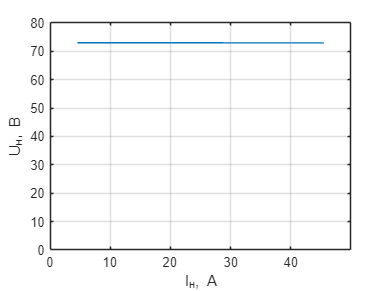

figure
plot(I_n1max, U_n1max);
ylabel("U_н, В");
xlabel("I_н, А");
ylim([0 max(U_n1max)*1.1]);
xlim([0 max(I_n1max)*1.1]);
grid("on");

Энергетические характеристики

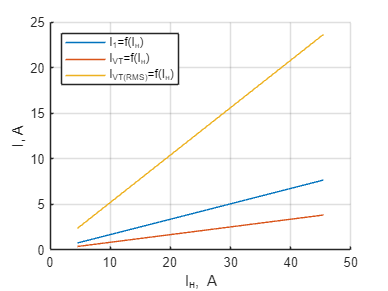

figure
ylabel("I, A")
xlabel("I_н, A")
hold on;
plot(I_n1max, I_1);
plot(I_n1max, I_vt);
plot(I_n1max, I_vtRMS);
hold off;
grid on;
legend(["I_1=f(I_н)", "I_{VT}=f(I_н)", "I_{VT(RMS)}=f(I_н)"], "Location","northwest");

Энергетические характеристики инвертора

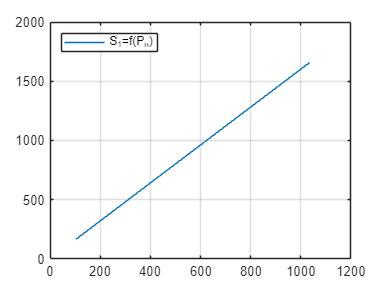

figure
ylabel("S, ВA")
xlabel("P_н, Вт")
plot(P_n1, S_n1);
grid on;
legend("S_1=f(P_н)", "Location","northwest")

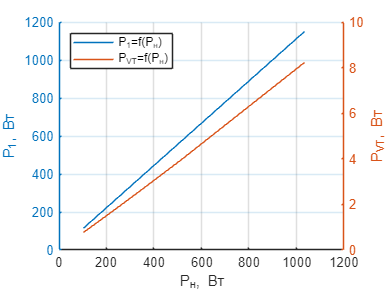

figure
xlabel("P_н, Вт")
hold on;
yyaxis left
ylabel("P_1, Вт")
plot(P_n1, P_1);
yyaxis right
ylabel("P_{VT}, Вт")
plot(P_n1, P_vt);
hold off;
grid on;
legend(["P_1=f(P_н)", "P_{VT}=f(P_н)"], "Location","northwest");

Подготовка данных моделирования для построения регулировочной характеристики

U_modReg = [0:0.5:1.9, 1.9];
Nagr.Res = 1;
Nagr.Ind = 2*Nagr.Res / f_nes;
U_n = [];
for i = 1:length(U_modReg)
    U_mod = U_modReg(i);
    sim("lr5mod.slx");
    U_n(i) = ans.U_n1max.Data(end);
end

Полученные данные сводим в таблицу

Table_reg = table(U_modReg.', U_n.', VariableNames=["Umod, В", "Uн, В"]);
disp(Table_reg);

    Umod, В     Uн, В  
    _______    ________

        0      0.042371
      0.5        36.471
        1        72.943
      1.5        109.41
      1.9        138.59



По данным таблицы строится регулировочная характеристика

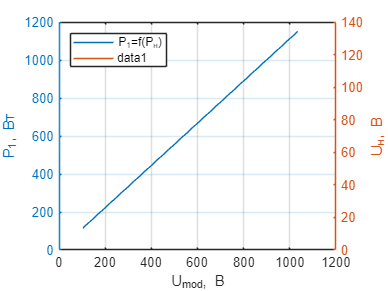

plot(U_modReg, U_n);
grid("on");
ylabel("U_н, В");
xlabel("U_{mod}, В");

Диаграммы тока питания, тока нагрузки и напряжение на нагрузки, тока и напряжения транзистора

При R = 1 Ом

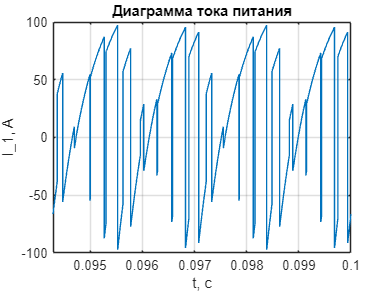

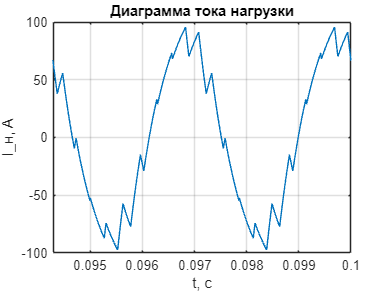

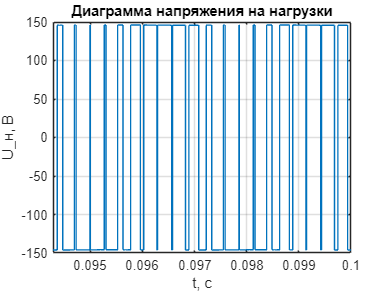

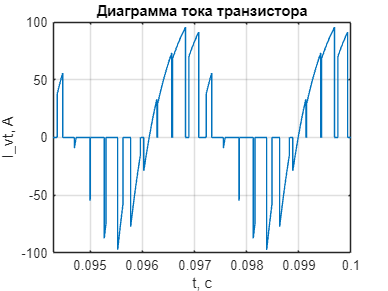

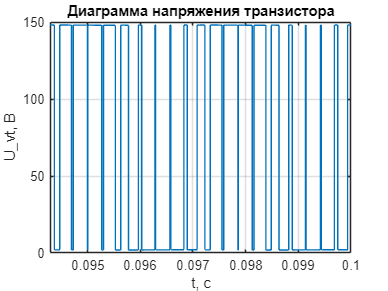

При R = 5 Ом

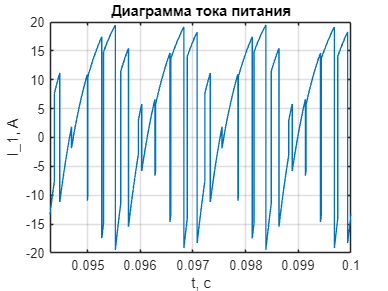

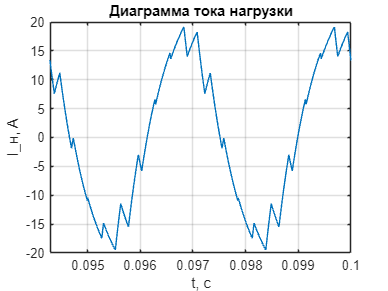

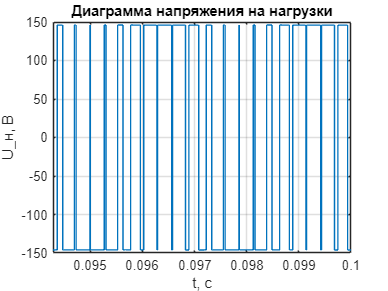

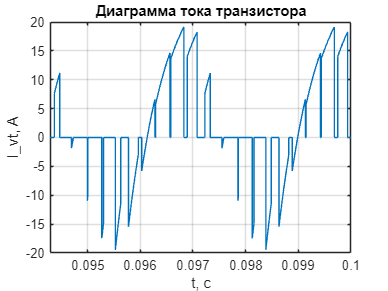

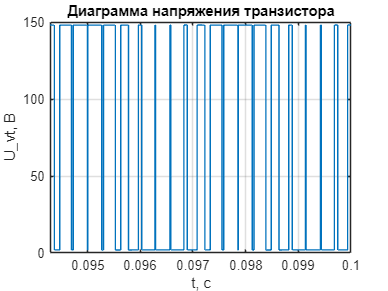

При R = 10 Ом

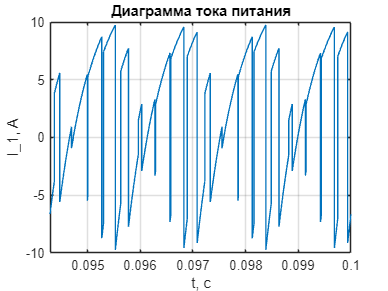

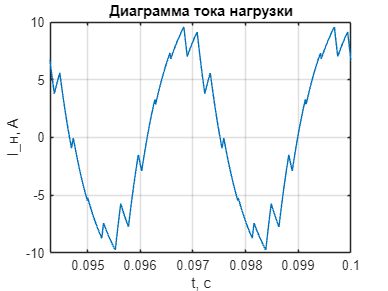

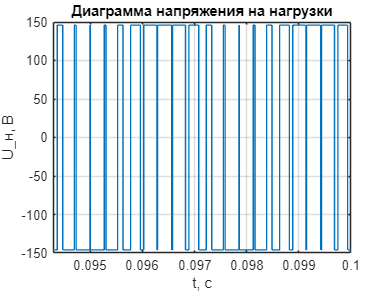

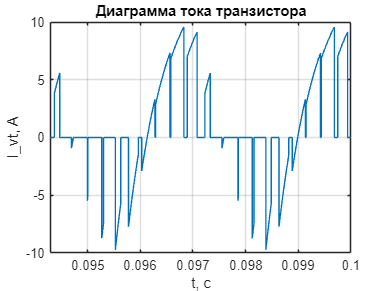

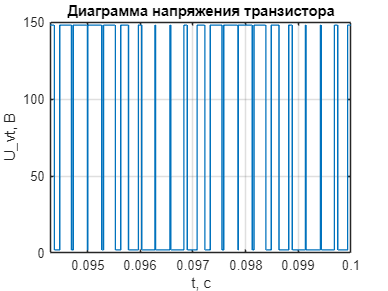

for i = [1, 5, 10]
    Nagr.Res = i;
    Nagr.Ind = 2*Nagr.Res / f_nes;
    sim("lr5mod.slx");
    fprintf("При R = %d Ом", Nagr.Res)
    figure
    ans.ScopeData1{1}.Values.plot;
    title("Диаграмма тока питания")
    ylabel("I_1, A");
    xlabel("t, c");
    xlim([0.1-2/f_preobr 0.1]);
    grid on;
    figure
    ans.ScopeData1{2}.Values.plot;
    title("Диаграмма тока нагрузки")
    ylabel("I_н, A");
    xlabel("t, c");
    xlim([0.1-2/f_preobr 0.1]);
    grid on;
    figure
    ans.ScopeData1{3}.Values.plot;
    title("Диаграмма напряжения на нагрузки")
    ylabel("U_н, В");
    xlabel("t, c");
    xlim([0.1-2/f_preobr 0.1]);
    grid on;
    figure
    ans.ScopeVT{1}.Values.plot;
    title("Диаграмма тока транзистора")
    ylabel("I_vt, A");
    xlabel("t, c");
    xlim([0.1-2/f_preobr 0.1]);
    grid on;
    figure
    ans.ScopeVT{2}.Values.plot;
    title("Диаграмма напряжения транзистора")
    ylabel("U_vt, В");
    xlabel("t, c");
    xlim([0.1-2/f_preobr 0.1]);
    grid on;
end

Выводы по работе